clear all
clear

Загрузка параметров

load curvefitting.mat

Описание данных с помощью функций (пытаемся использовать полиномы n-ой степени)

%   Строим модель, пытаемся описать все данные полиномом 5 степени poly5 
%   Все значения normalized by mean 1.061e+04 and std 2989


%   Разделить значения по расходам
%   значения начиная с 7500 (6 ая строка)

for i = 6:1:11

%   получение сил/моментов, соответствующих расходам
%   для каждой из сил строим и интерполируем(аппроксимируем) зависимость от частоты

%   Сохранение соответств. сил/моментов в 

Fr_cell{i-5}=Fr_comb{1,i};
Fx_cell{i-5}=Fx_comb{1,i};
Fy_cell{i-5}=Fy_comb{1,i};
Fz_cell{i-5}=Fz_comb{1,i};

Mr_cell{i-5}=Mr_comb{1,i};
Mx_cell{i-5}=Mx_comb{1,i};
My_cell{i-5}=My_comb{1,i};
Mz_cell{i-5}=Mz_comb{1,i};


end
%   объединяем, получаем ячейки, 
%   где строки - значения по x,y,z,r а столбцы - расходы
%   в самих ячейках вектор из 6 значений (точек) силы/момента для данного
%   расхода по возрастанию идут значения сил от скорости вращения от 7500 до 15000 

F_all=[Fx_cell; Fy_cell; Fz_cell; Fr_cell];
M_all = [Mx_cell; My_cell; Mz_cell; Mr_cell];

FplusM = [F_all; M_all];

% save("FplusM.mat","FplusM", "RPM_comb")
% FM_all = {F_all; M_all}
% Fr_cell(1,i) - получение силы, соответствующей расходу

Интерполяция визуально для каждого значения силы или момента

k=1;             %номер графика, их счётчик количества
for i = 1:8      %по всем силам и моментам
    for j = 1:6 %по расходам (по столбцам)
 %для всех строк (8)
    plotdata = FplusM{i,j};

    figure("Name","Силы/моменты от расхода")
%         subplot(2,3,j)
%     legstr=sprintf('Расход %.1f л/мин',k);
%     title('F'+legstr)
%         xlabel('Угл. скорость, об/мин')
%         ylabel('F [M], Н [Нм]')
%     legend(legstr,"Location","best")
%     plot(RPM_comb,cell2mat(Fr_cell(1,k)))
%     plots{k}=plot(RPM_comb,plotdata{k},'b--o')

% % Сравнение полинома и интерполяции, кубическая работает лучше!
%createFit_poly_vs_cubic(RPM_comb,plotdata);
    k
    % Сохранить каждый результат в переменную с соответствующим именем
    % (расход и частота)
     [fitresult{i,j}, gof{i,j}] = createFit_cubic_interp(RPM_comb,plotdata);  
     
%   Сохранение графиков в переменную
% plots{k}=plot(RPM_comb,plotdata,'b--o');
    k=k+1;
    end
end

Получение силы, на основании заданного расхода

clf % очистка графиков в выводе

% Ввод частоты, расхода - получение значения силы
% задаем расход (ячека определяет проекцию вектора и расход,
% первый индекс m = 1 - Fx, m=2 - Fy, m=3 - Fz, m=4 - Fr, m=5 - Mx и т.д. m=8 - Mr аналогично,
% второй индекс n = 1 - расход 1 л/мин, n=6 - расход 6 л/мин

prompt = 'Выберите величину для поиска Fx, Fy, Fz, Fr, Mx, My, Mz, Mr ?:';
str = input(prompt, 's');
if isempty(str)
    str = 'Fx';
    m=1;
    FM_flag=1; % Флаг это сила или момент? 1 - сила, 2 - момент
elseif str == "Fx"
    m=1;
    FM_flag=1;
elseif str == "Fy"
    m=2;
    FM_flag=1;
elseif str == "Fz"
    m=3;
    FM_flag=1;
elseif str == "Fr"
    m=4;
    FM_flag=1;
elseif str == "Mx"
    m=5
    FM_flag=2;
elseif str == "My"
    m=6;
    FM_flag=2;
elseif str == "Mz"
    m=7;
    FM_flag=2;
elseif str == "Mr"
    m=8;
    FM_flag=2;
end

prompt = 'Значение требуемого расхода от 1 до 6:';
n = input(prompt);
if isempty(n)
    n=1;
end

% m = 1; % выбор величины для поиска 1-4 = силы, 5-8 = моменты, см. выше
% n=1; % расход в л/мин по шкале от 1 до 6

% Простое задание частоты вращения в об/мин в пределах от 7500 до 15000
% RPMtofind = 9500;
prompt = 'Значение частоты от 7500 до 15000 об/мин:';
RPMtofind = input(prompt);
if isempty(RPMtofind)
    RPMtofind=7500;
end

plotdata = FplusM{m,n}; 

% Получаем значение силы на заданной частоте
ForceOrMoment = getForceOnRPMandFlow(RPM_comb,plotdata,RPMtofind,FM_flag)


Построение поверхности (пространства всех значений) и интерполяция

clf % очистка графиков в выводе
FM_flag=0;           % Если не 1 или не 2, то не строим графики, получаем только силу. Если отлично от 0 то getForceOnRPMandFlow возвращает fitdata
Q=[1 2 3 4 5 6]

Q =      1     2     3     4     5     6


RPM_all = 1:15000

RPM_all =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



F_points_all = zeros(6,15000);
F_points_all(F_points_all==0) = NaN;

% нужно посчитать значения сил в промежуточных расходах

m=6

m = 6

% for m = 1:8         %по всем силам  %моментам 5-8 (построчно)
    for n = 1:6     %по расходам (по столбцам)
        plotdata = FplusM{m,n}; % получаем значение вектора силы или момента на частотах
        for RPMtofind = 7500:100:15000
            % Получаем значение силы на заданной частоте и расходе
            Force_point = getForceOnRPMandFlow(RPM_comb,plotdata,RPMtofind,FM_flag);
            formatSpec = 'Расход: %4.0f л/мин, частота: %4.0f об/мин, сила: %4.4f Н\n';
            fprintf(formatSpec,n,RPMtofind,Force_point)
            % Нужно записать в ячейку матрицы значение силы
            F_points_all(n,RPMtofind) = Force_point;
            
        end
    end

Расход:    1 л/мин, частота: 7500 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 7600 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 7700 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 7800 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 7900 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 8000 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 8100 об/мин, сила: 0.0002 Н
Расход:    1 л/мин, частота: 8200 об/мин, сила: 0.0001 Н
Расход:    1 л/мин, частота: 8300 об/мин, сила: 0.0001 Н
Расход:    1 л/мин, частота: 8400 об/мин, сила: 0.0001 Н
Расход:    1 л/мин, частота: 8500 об/мин, сила: 0.0000 Н
Расход:    1 л/мин, частота: 8600 об/мин, сила: -0.0000 Н
Расход:    1 л/мин, частота: 8700 об/мин, сила: -0.0001 Н
Расход:    1 л/мин, частота: 8800 об/мин, сила: -0.0001 Н
Расход:    1 л/мин, частота: 8900 об/мин, сила: -0.0002 Н
Расход:    1 л/мин, частота: 9000 об/мин, сила: -0.0003 Н
Расход:    1 л/мин, частота: 9100 об/мин, сила: -0.0004 Н
Расход:    1 л/мин, часто

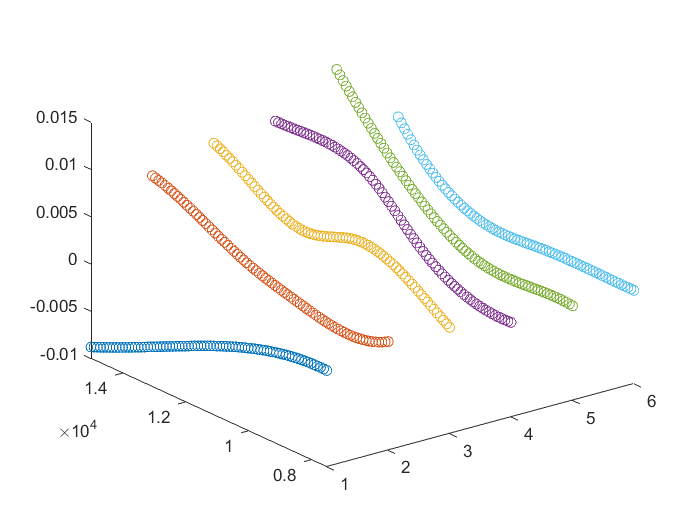



%Построение поверхностей
F_tr=F_points_all.';
[X,Y]=meshgrid(Q,RPM_all);
plot3(X,Y,F_tr,'marker',"o")

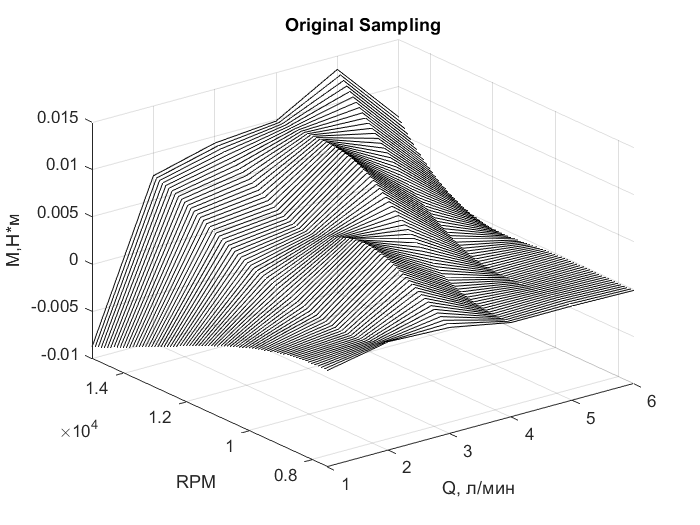

surf(X,Y,F_tr)
title('Линейная интеполяция');

xlabel('Q, л/мин')
ylabel('RPM')
if m<=4
   zlabel('F, Н')
else
   zlabel('М,Н*м') 
end
grid on

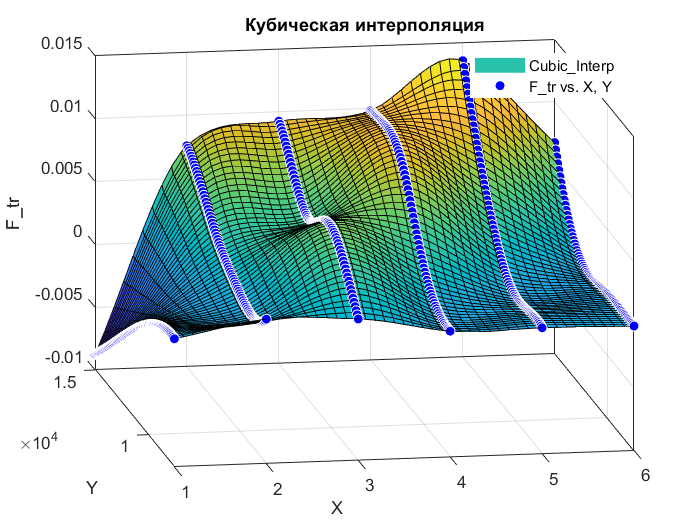


% КУбическая интерполяция
[fitresult_cubic, gof_cubic] = Cubic_Interp(X,Y,F_tr);

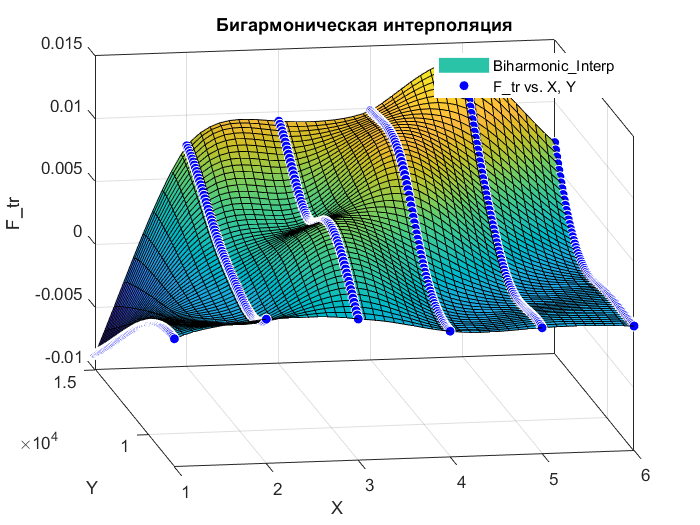

% Бигармоническая интерполяция
[fitresult_biharm, gof_biharm] = Biharmonic_Interp(X,Y,F_tr);


% save('F_points.mat','F_points_all')

DEBUG

% load("F_points.mat","F_points_all")
% F_points_all
% RPM_lin = 7500:15000